clear;
m=1; k=1; D=1; a=1; tau=1e15;
omega0 = sqrt(k/m);
tspan = [1, 4000];
omegarange = linspace(0, 2.5*omega0, 201);
Drange = linspace(0.001, 0.2, 10);
plotem = true;
x0 = [0 0];

% ✅ FIX 1: Define odefcn inline (was missing entirely)
% Assumed form: driven damped oscillator  ẍ = -(k/m)x - (D/m)ẋ + (a/m)*sin(omega*t)
% with tau as a slow turn-on envelope: forcing *= (1 - exp(-t/tau))
odefcn = @(t,x,m,k,D,a,omega,tau) [
    x(2);
    -(k/m)*x(1) - (D/m)*x(2) + (a/m)*sin(omega*t)*(1 - exp(-t/tau))
];

tic
index = 0;
for omega = omegarange
    index = index + 1;
    jindex = 0;
    for D = Drange
        jindex = jindex + 1;
        [t,x] = ode45(@(t,x) odefcn(t,x,m,k,D,a,omega,tau), tspan, x0);
        X{index,jindex} = x(:,1);
        T{index,jindex} = t;
        % ✅ FIX 2: length1() doesn't exist, use length()
        range = round(3*length(t)/4):length(t);
        A(index,jindex) = max(x(range,1));
    end
end
toc

Elapsed time is 14.270207 seconds.


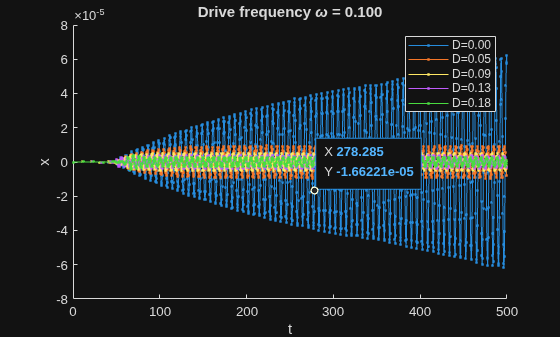

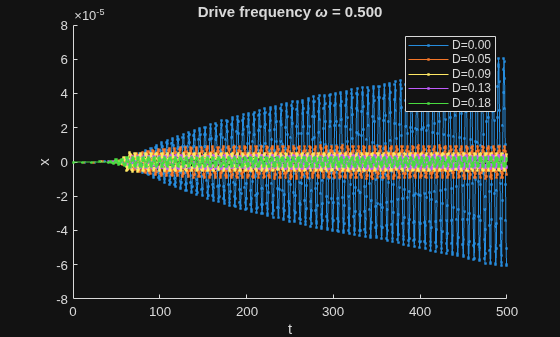

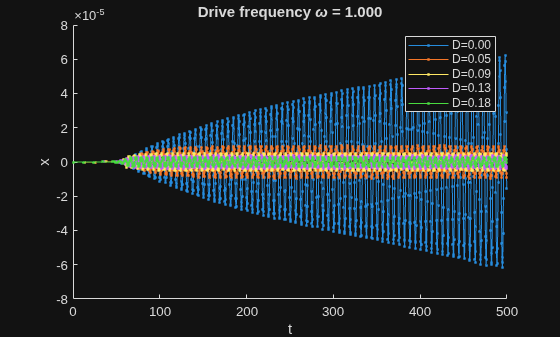

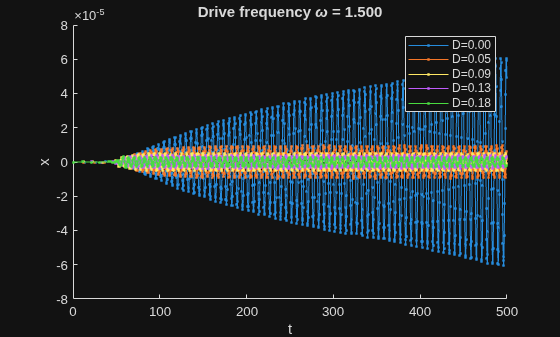

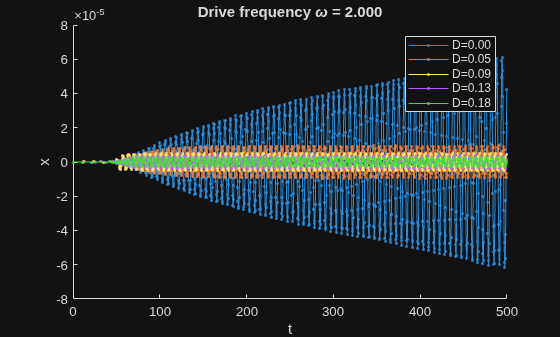

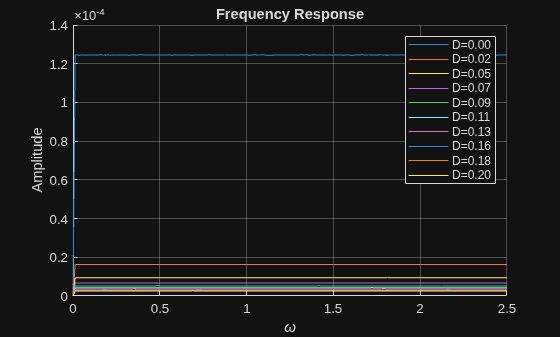


if plotem
    tmin = 0; tmax = tspan(2)/8;

    % ✅ FIX 3: Nfreq was undefined/inconsistent, define it
    % ✅ FIX 4: targetfreuqncies typo fixed, use targetfrequencies
    targetfrequencies = [0.1, 0.5, 1, 1.5, 2] * omega0;

    % ✅ FIX 5: repmat (not remat), and correct args: repmat(omegarange, [length(V),1])
    V = targetfrequencies;
    AA = repmat(omegarange, [length(V), 1]);          % [nFreqs x nOmega]
    Vmat = repmat(V(:), [1, length(omegarange)]);     % [nFreqs x nOmega]
    [~, indexrange] = min(abs(AA - Vmat), [], 2);     % ✅ FIX 6: min() syntax corrected

    for index = indexrange'
        figure; hold on;
        for jindex = 1:2:length(Drange)
            trange = find(T{index,jindex} > tmin & T{index,jindex} < tmax);
            % ✅ FIX 7: plot() args were malformed
            plot(T{index,jindex}(trange), X{index,jindex}(trange), ...
                '.-', 'DisplayName', sprintf('D=%.2f', Drange(jindex)));
        end
        xlabel('t'); ylabel('x');
        legend;
        title(sprintf('Drive frequency \\omega = %.3f', omegarange(index)));
    end

    % Bonus: plot amplitude vs drive frequency for each D
    figure; hold on;
    for jindex = 1:length(Drange)
        plot(omegarange, A(:,jindex), 'DisplayName', sprintf('D=%.2f', Drange(jindex)));
    end
    xlabel('\omega'); ylabel('Amplitude');
    title('Frequency Response'); legend; grid on;
end